# 1. Извлечение гармоник из спектра

## Красницкий Никита

Задача: получить значения амплитуд и частот гармоник из общего спектра звука.

В пункте 1.1 созданы общие вектора и константы. Тут они подгружаются

clear all
close all
load('1.Load Data.mat');

Исследуемый звук

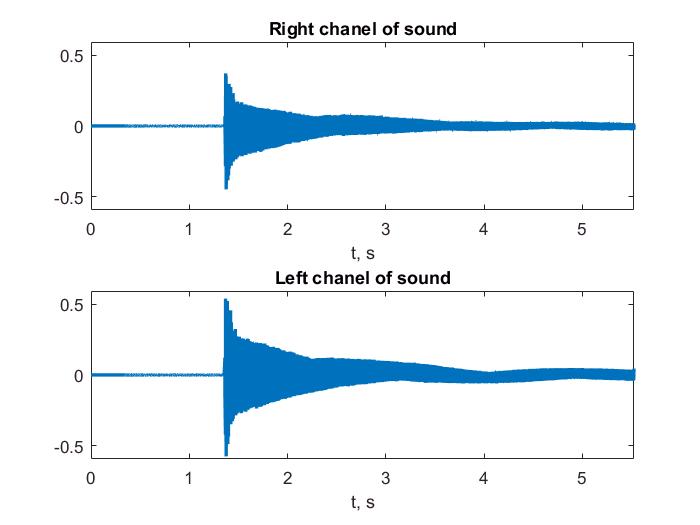

%sound(x, fs);
M = 1.1 * max(max(x));

figure
subplot(2,1,1);
plot(t, x(:,1), 'LineWidth', 2);     
ylim([-M M]);
xlim([0 t(end)]);
title('Right chanel of sound');
xlabel('t, s');

subplot(2,1,2);
plot(t, x(:,2), 'LineWidth', 2); 
ylim([-M M]);
xlim([0 t(end)]);
title('Left chanel of sound');
xlabel('t, s');

## Спектры

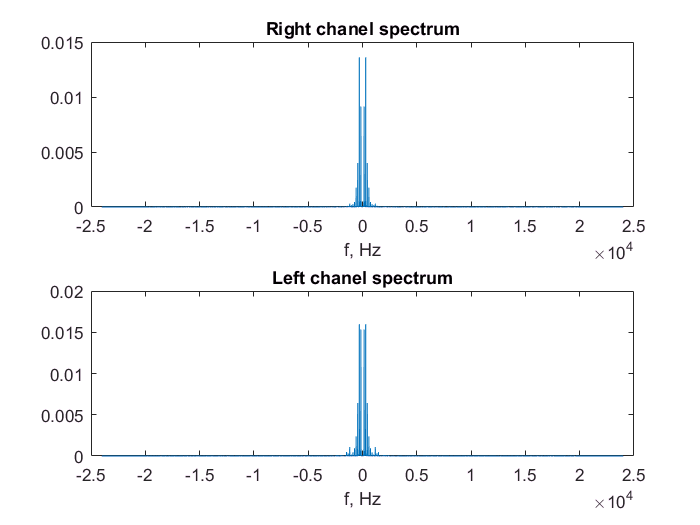

X(:,1) = fft(x(:,1)) / N;
X(:,2) = fft(x(:,2)) / N;

figure
subplot(2,1,1);
plot(f, abs(fftshift(X(:,1))));
title('Right chanel spectrum');
xlabel('f, Hz');

subplot(2,1,2);
plot(f, abs(fftshift(X(:,2))));
title('Left chanel spectrum');
xlabel('f, Hz');

## Извлечение гармоник из спектра

Для захвата гармоник используется алгоритм, который выделяет локальные максимумы спектра. Локальные максимумы могут быть созданы шумом в большом количестве. Для уменьшения влияния локальных максимумов шумов задаются параметры "Минимального шага между максимумами" и "Минимальнаявеличина максимума". В общем случае эти параметры задаются пользователем (функция HarmonicsExtraction).

Данные параметры, для примера, были выбраны с учетом природы исследуемых спектров - звуки музыкальных инструментов. Минимальный шаг частот был выбран 60Гц, так как самая низкая из исследуемых нот - нота ДО большой октавы, которой соответствует колебание с частотой 65Гц. Минимальной амплитудой гармоники была принята амплитуда превышающая одну сотую от максимальной амплитуды гармоник спектра.

Значения частот гармоник будут хранится в "FharmRaw". Данные названы сырыми, так как кроме основного тона и его обертонов возможен захват шумов. Далее захваченые локальные максимумы будут отфильтрованы

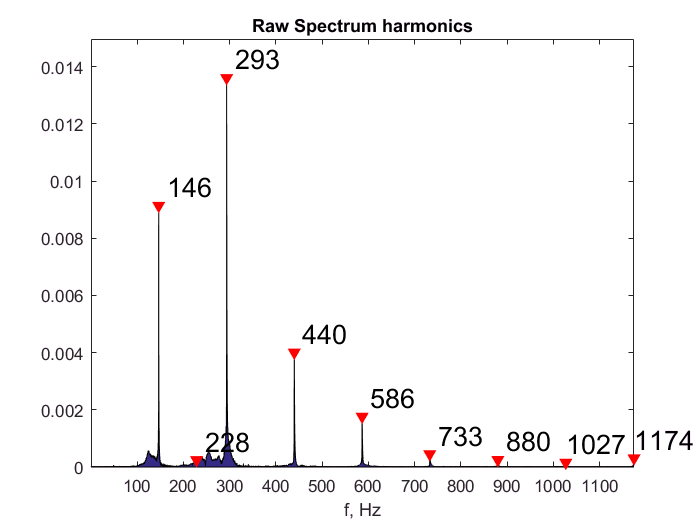

Xp = abs(fftshift(X(:,1)));
Xp = Xp(N/2 + 1:end);
fp = f(N/2 + 1:end);
MinFreqStep = 60;
MinAmplitude = max(max(Xp)) / 100;

[pksRaw, FharmRaw] = findpeaks(Xp, fp, 'MinPeakDistance', MinFreqStep...
                          ,'MinPeakHeight', MinAmplitude);

figure
area(fp, Xp);
hold on
plot(FharmRaw, pksRaw, 'rv', 'MarkerFaceColor', 'r');
yScaleAdd = max(pksRaw)*0.05; 
cellpeaks = cellstr(num2str(round(FharmRaw', 0)));
text(FharmRaw, yScaleAdd+pksRaw, cellpeaks, 'FontSize', 16);
ylim([0 max(pksRaw)+2*yScaleAdd]);
xlim([fp(1) FharmRaw(end)])
hold off
title('Raw Spectrum harmonics');
xlabel('f, Hz');

Осуществляется поиск основной гармоники с расчетом на то, что у основной гармоники будет больше всего кратных по частоте обертонов. Вектор "CompareVector" будет хранить количество кратных обертонов для каждой из гармоник. Индекс вектора соответствует номеру гармоники.

Nf = length(FharmRaw);
CompareVector = zeros(1, Nf);
ErrorTresholdDivision = 0.05;

for i = 1:Nf
   for j = 1:Nf
        if FharmRaw(i) < FharmRaw(j)
            integerVal = floor(FharmRaw(j)/FharmRaw(i));
            floatVal   = FharmRaw(j)/FharmRaw(i);
            freqDifference = abs(floatVal-integerVal);
            if freqDifference < ErrorTresholdDivision
                CompareVector(i) = CompareVector(i) + 1;
            end
        end
    end
end
disp(['Кратность гармоник - ', num2str(CompareVector)]);

Кратность гармоник - 7  0  1  1  1  0  0  0  0


Ниже осуществляется поиск номера гармоники с самым большим количеством кратных обертонов. Найденый основной тон будет хранится в "F0"

BaseVal = max(CompareVector);
BaseFreqIndex = 0;

for i = 1:length(CompareVector)
   if BaseVal == CompareVector(i)
       BaseFreqIndex = i;
   end
end

F0 = FharmRaw(BaseFreqIndex);

Предполагая что основной тон найден верно все некратные основному тону гармоники будут отсеяны. Отфильтрованый вектор гармоник хранится в "Fharm"

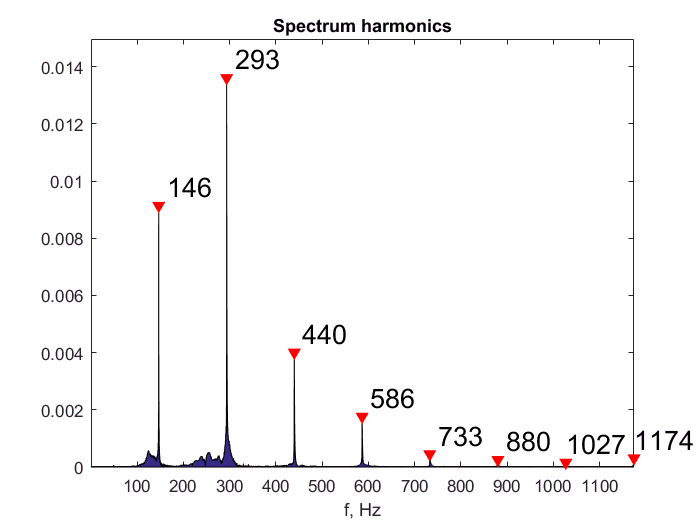

F0 = FharmRaw(1);
ErrorThreshold = 0.05;
FharmCnt = 0;
Fharm    = 0;
pks      = 0;

for i = 1:length(FharmRaw)
    integerVal = floor(FharmRaw(i)/F0);
    floatVal   = FharmRaw(i)/F0;
    freqDifference = abs(floatVal-integerVal);
    if ( freqDifference < ErrorThreshold )
        FharmCnt = FharmCnt+1;
        Fharm(FharmCnt) = FharmRaw(i);
        pks(FharmCnt) = pksRaw(i);
    end
end

figure
area(fp, Xp);
hold on
plot(Fharm, pks, 'rv', 'MarkerFaceColor', 'r');
yScaleAdd = max(pks)*0.05; 
cellpeaks = cellstr(num2str(round(Fharm', 0)));
text(Fharm, yScaleAdd+pks, cellpeaks, 'FontSize', 16);
ylim([0 max(pks)+2*yScaleAdd]);
xlim([fp(1) Fharm(end)])
hold off
title('Spectrum harmonics');
xlabel('f, Hz');

Данные о частотах гармоник и их амплитудах сохраняются для дальнейшего использования

fileName = '1.Harmonics Frequencies.mat';
save(fileName, 'Fharm', 'pks');